img = imread("X:\Enhance\images\5.png");


img = imread('images/6.png');
[rows, cols, dim] = size(img);
[b, g, r] = splitChannels(img);
result = zeros(rows, cols, 3);
result = mergeChannels(b, g, r);
img0 = imresize(result, [512, 512]);



result1 = adapt_histogram(img);
normalizedImage = result1;

r = normalizedImage(:, :, 1);
g = normalizedImage(:, :, 2);
b = normalizedImage(:, :, 3);

normalizedRedBand = normalizeBand(r, 0, 255);
normalizedGreenBand = normalizeBand(g, 0, 235);
normalizedBlueBand = normalizeBand(b, 0, 245);

normalizedImage = cat(3, normalizedBlueBand, normalizedGreenBand, normalizedRedBand);
img1 = imgaussfilt(normalizedImage, 11);
%imshow(res);

result2 = normalizedImage;
smooth = result2;
res = homomorphic(smooth);
res = imgaussfilt(res, 11);
img2 = res;
%imshow(img2);

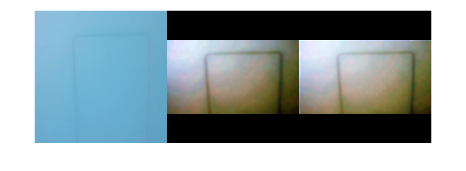

images= {img0,img1,img2};
montage(images, 'Size', [1, 3])